%Symbolic Assignment, Mechanic of Machinery

%Preliminary Coordinates
format short

O2 = [0,-0.6,.05];
O4 = [0,0,1.5];
B = [0,.35,-.085];
O2O4 = sqrt(sum((O2-O4).^2));
O4B = sqrt(sum(B.^2));

gamma = atan((O2(2)-O4(2))/(O2(3)-O4(3)));
beta = atan(-B(3)/B(2));

n = 1000;
theta_target = deg2rad(linspace(-60,0,n));

%Solving for L_AC
syms theta alpha O2B
eq1 = O2O4^2 == O4B^2+O2B^2-2*O4B*O2B*cos(alpha)

$$eq1 = \frac{197}{80}={\mathrm{O2B}}^{2}-\frac{\sqrt{5189}\,\cos\left(\alpha \right)\,\mathrm{O2B}}{100}+\frac{5189}{40000}$$

eq1 = O2B^2 == O4B^2+O2O4^2-2*O4B*O2O4*cos(gamma+pi/2+theta-beta)

$$eq1 = {\mathrm{O2B}}^{2}=\frac{5837171772030241}{2251799813685248}-\frac{5090843301503403\,\cos\left(\theta +\frac{62145773401305231}{36028797018963968}\right)}{4503599627370496}$$

eq2 = sin(gamma+pi/2+theta-beta)/O2B == sin(alpha)/O2O4

$$eq2 = \frac{\sin\left(\theta +\frac{62145773401305231}{36028797018963968}\right)}{\mathrm{O2B}}=\frac{4\,\sqrt{5}\,\sqrt{197}\,\sin\left(\alpha \right)}{197}$$

sol = solve([eq1,eq2],[O2B,alpha]);
O2B_sol = sol.O2B(1)

$$O2B\_sol = \frac{\sqrt{11674343544060482-5090843301503403\,\cos\left(\theta +\frac{62145773401305231}{36028797018963968}\right)}}{67108864}$$

alpha_sol = sol.alpha(1)

$$alpha\_sol = \mathrm{asin}\left(\frac{16777216\,\sqrt{5}\,\sqrt{197}\,\sin\left(\theta +\frac{62145773401305231}{36028797018963968}\right)}{5\,\sqrt{11674343544060482-5090843301503403\,\cos\left(\theta +\frac{62145773401305231}{36028797018963968}\right)}}\right)$$

%Minimal Transmission Angle
O4BA = alpha_sol;
O4BA_all = rad2deg(double(subs(O4BA,theta_target)));

figure();
plot(linspace(-60,0,n),O4BA_all,'Color',[0.1 0 0.8])
grid on

theta_time = -60 + 60/5*out.mul2.Time;
theta_multibody = 13.65+rad2deg(out.mul2.Data); %Additional angle from design
size_mul = size(out.mul2.Time)
for i = 1: size_mul(1)
    if theta_multibody(i) > 90
        theta_multibody(i) = 180-(13.65+rad2deg(out.mul2.Data(i)));
    end
end

hold on
plot(theta_time,theta_multibody,'--r')
ylim([40,90])
title("Transmission Angle α")
xlabel('Altitude Angle (Deg)')
ylabel('Transmission Angle (Deg)')
BCA_min = min(O4BA_all)
legend('Symbolic','Mutibody',Location='best')
hold off


%Length AC
O2B_all = double(subs(O2B_sol,theta_target));
figure();
plot(linspace(-60,0,n),O2B_all,'Color',[0.1 0 0.8])
hold on
grid on
% length = .95+.9-out.mul.Data; %length of pistons - intersect length
% theta_time = -60+60/5*out.mul.Time;
% plot(theta_time,length,'--r')
title("Combined Length of Piston O_2B")
xlabel('Altitude Angle (Deg)')
ylabel('Length (m)')
AC_min = min(O2B_all)

AC_min = 1.3083

AC_max = max(O2B_all)

AC_max = 1.6630

del_AC = AC_max-AC_min

del_AC = 0.3548

legend('Symbolic','Mutibody',Location='best')

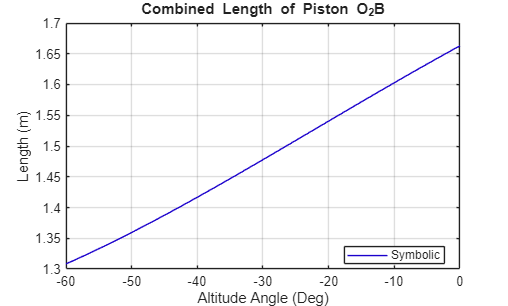

hold off


%Determine Position C
C = O4+O4B*[0,cos(theta-beta),sin(theta-beta)];

%Panel Position Analysis
panel_top = O4+1.5/2*[0,cos(theta),sin(theta)];
panel_bottom = O4-1.5/2*[0,cos(theta),sin(theta)];
panel_top_drawx = double(subs(panel_top(1),theta_target));
panel_top_drawy = double(subs(panel_top(2),theta_target));
panel_top_drawz = double(subs(panel_top(3),theta_target));
panel_bottom_drawx = double(subs(panel_bottom(1),theta_target));
panel_bottom_drawy = double(subs(panel_bottom(2),theta_target));
panel_bottom_drawz = double(subs(panel_bottom(3),theta_target));


panel_con = O4+B(2)*[0,cos(theta),sin(theta)];
panel_con_drawx = double(subs(panel_con(1),theta_target));
panel_con_drawy = double(subs(panel_con(2),theta_target));
panel_con_drawz = double(subs(panel_con(3),theta_target));


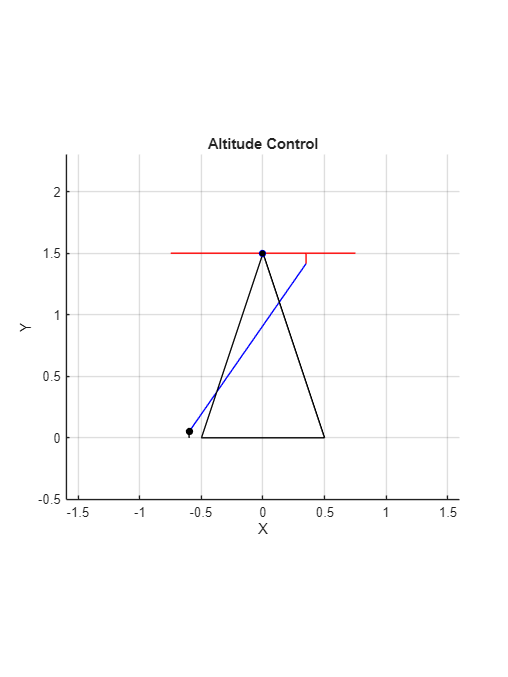

%Visualise

%2D
figure('Position', [100, 100, 1200, 1600])
hold on
axis equal
grid on
xlabel('X')
ylabel('Y')
title('Altitude Control')
xlim([-1.6, 1.6])
ylim([-0.5, 2.3])

h_AB = animatedline('color','black','LineStyle',"--");
h_BC = animatedline('color','green','LineStyle',"--");
h_CA = animatedline('color','blue');
h_base = animatedline('color','black');
h_base_con = animatedline('color','black');

Cx_draw = double(subs(C(1),theta_target));
Cy_draw = double(subs(C(2),theta_target));
Cz_draw = double(subs(C(3),theta_target));

%Draw panel
h_panel = animatedline('Color','red');
h_panel_con = animatedline('Color','red');

p_base_con = plot(O2(2),O2(3),'ko',markerfacecolor = 'black',markersize = 5);
p_panel_piv = plot(O4(2),O4(3),'bo',markerfacecolor = 'black',markersize = 5);

%Simulate
%addpoints(h_AB,[A(2),B(2)],[A(3),B(3)]);
addpoints(h_base,[-.5,0,.5,-.5],[0,O4(3),0,0]);
addpoints(h_base_con,[O2(2),O2(2)],[0,O2(3)]);
skip = floor(n/40);


for i = 1:skip:n
    %clearpoints(h_BC);
    clearpoints(h_CA);
    clearpoints(h_panel);
    clearpoints(h_panel_con);
    
    
    %addpoints(h_BC,[B(2),Cy_draw(i)],[B(3),Cz_draw(i)]);
    addpoints(h_CA,[Cy_draw(i),O2(2)],[Cz_draw(i),O2(3)]);
    addpoints(h_panel,[panel_top_drawy(i),panel_bottom_drawy(i)],[panel_top_drawz(i),panel_bottom_drawz(i)]);
    addpoints(h_panel_con,[Cy_draw(i),panel_con_drawy(i)],[Cz_draw(i),panel_con_drawz(i)]);
    drawnow 

    pause(.1)
end

%clearpoints(h_BC);
clearpoints(h_CA);
clearpoints(h_panel);
clearpoints(h_panel_con);


%addpoints(h_BC,[B(2),Cy_draw(i)],[B(3),Cz_draw(i)]);
addpoints(h_CA,[Cy_draw(n),O2(2)],[Cz_draw(n),O2(3)]);
addpoints(h_panel,[panel_top_drawy(n),panel_bottom_drawy(n)],[panel_top_drawz(n),panel_bottom_drawz(n)]);
addpoints(h_panel_con,[Cy_draw(n),panel_con_drawy(n)],[Cz_draw(n),panel_con_drawz(n)]);

drawnow 

pause(.1)

